#  Source and Flare Detection for Poisson Noise Data 

Coded by: Yevgeniya Korotinsky (313622078)

## Workflow Description

First, we choose specific values for the background expectancy (B), false alarm 

probability ($\beta$), PSF width ($\sigma$) and flare signal decay time ($\tau$) , and provide the following list of example plots:

- 2D cuts of simulated input data (poisson random image)

- Flare model 

- 2D cuts of signal template (PSF)

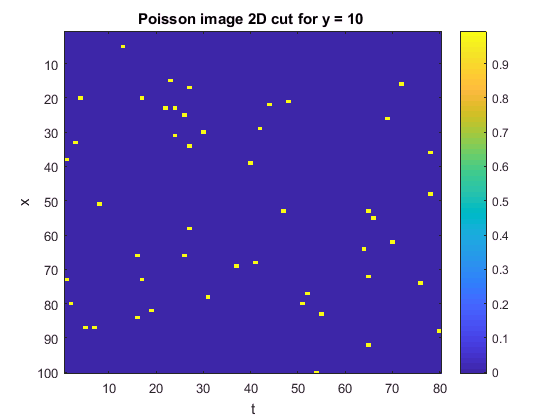

clc; clear; close all;

% Define parameters
size_IMG_xy = 100;        %| image size in xy
size_IMG_t = 80;          %| image size in t
size_TEMP_xy = 20;        %| PSF size in xy
size_TEMP_t = 16;         %| PSF size in t
B = 0.005;                %| background expectancy
tau = 1.2;                %| flare decay time
Decay_rate = 1/tau;       %| flare decay rate
Sigma = 2;                %| PSF Gaussian std
beta = 0.001;             %| false alarm prob.
time_range = floor(size_TEMP_t/2):1:size_TEMP_t;   %| time range for flare signal

% Generate Poisson random image with background subtraction
% For bg subtraction pass '1' as the function input parameter
% For no bg subtraction pass '0' as the function input parameter
M = makeImg(B,size_IMG_xy,size_IMG_t,1);

% Plot 2D image slice
plotImage(M,'y',10,'Poisson image')

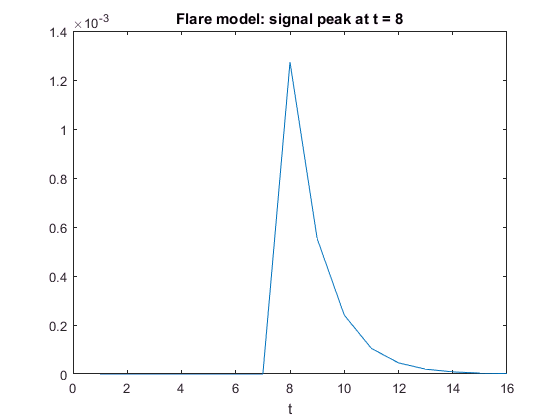

% Generate normalized template
[PSF,Fmodel] = makeTemp(size_TEMP_xy,size_TEMP_t,Sigma,Decay_rate,time_range);

% Plot flare model
plot(1:size_TEMP_t,Fmodel)
xlabel('t')
title(['Flare model: signal peak at t = ' num2str(time_range(1))])

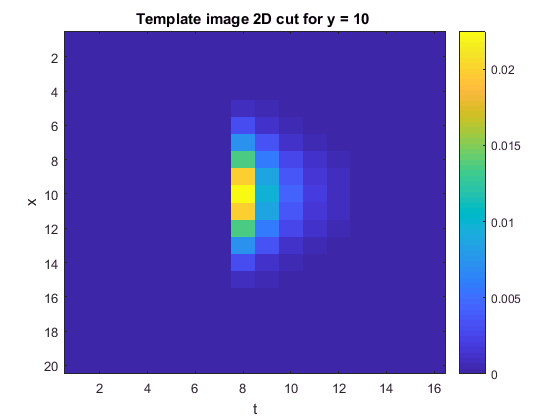

% Plot 2D template slices
plotImage(PSF,'y',10,'Template image')

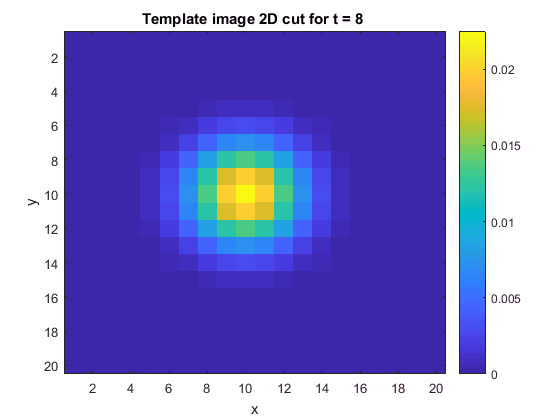


plotImage(PSF,'t',8,'Template image')

Since the flux of the searched source is uknown apriori, we would like to find the flux threshold value Fth in order to construct the Poisson matched filter (PMF) and Sth in order to test the local maxima value in the filtered image S (thresholds determination algorithm can be found in the documentation of 'getThresholdsPoisson' function ).

% Get threshold values 
[Fth,Sth] = getThresholdsPoisson(size_IMG_xy,size_IMG_t,beta,B,Sigma,PSF);

iteration: 1
Fth: 2.0020
Sth: 4.5809
Sf: 1.2074

iteration: 2
Fth: 3.7991
Sth: 6.6676
Sf: 1.6421

iteration: 3
Fth: 4.0654
Sth: 6.4658
Sf: 1.6917

iteration: 4
Fth: 3.8270
Sth: 6.2960
Sf: 1.6474

Summary
Initial Fth: 2.0020
Final Fth: 3.8270
Sth: 6.2960


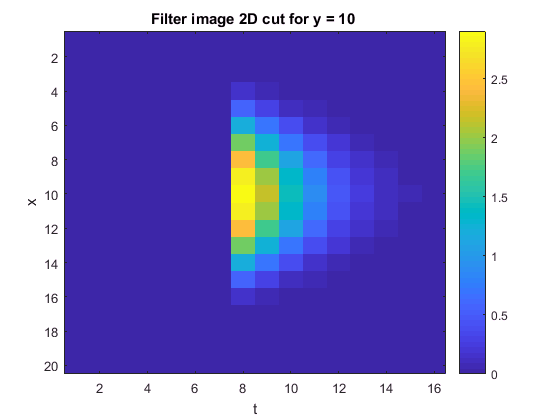

% Generate PMF 
Filter_OPT = log(1 + (Fth*PSF)/B);
plotImage(Filter_OPT,'y',10,'Filter image')

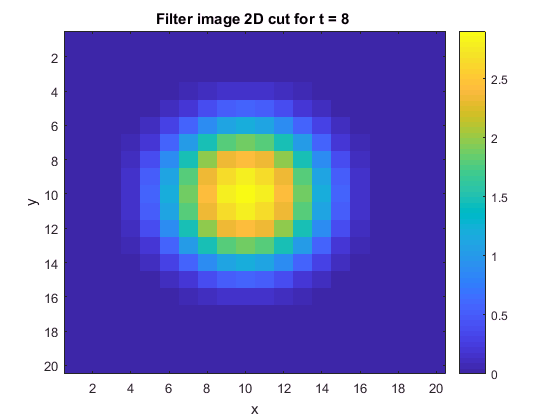

% Plot 2D optimal filter slices
plotImage(Filter_OPT,'t',8,'Filter image')

We filter the random image (M) with 2 filters:

- Filter_OPT

- PSF, this is the Gaussian matched filter used in the naive method

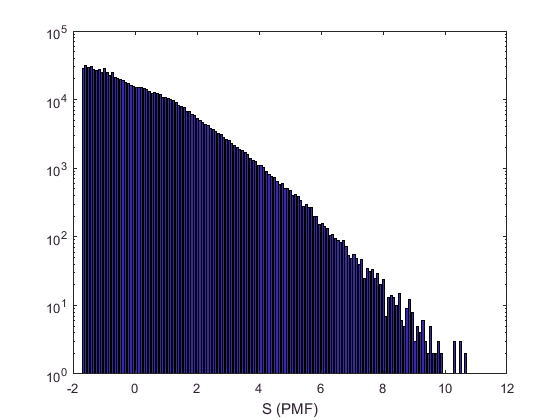

% Filtering (via 2 methods)
S_PMF = imfilter(M,Filter_OPT); % Method 1: Poisson matched filter
S_PSF = imfilter(M,PSF); % Method 2 (naive): Gaussian matched filter

Sth_G = prctile(S_PSF(:),(1 - beta)*100); % determine S threshold for naive case

% Plot unnormalized S_PMF distribution (logarithmic Y-axis)
nbins = 150;
[counts,centers] = hist(S_PMF(:),nbins);
bar(centers,counts) 
set(gca,'YScale','log')
xlabel('S (PMF)')

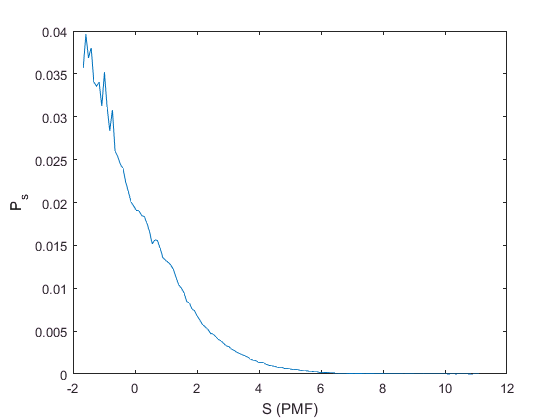

% Plot normalized Probability distribution of S_PMF (Ps)
Ps = counts/sum(counts);
plot(centers,Ps)
xlabel('S (PMF)')
ylabel('P_s')

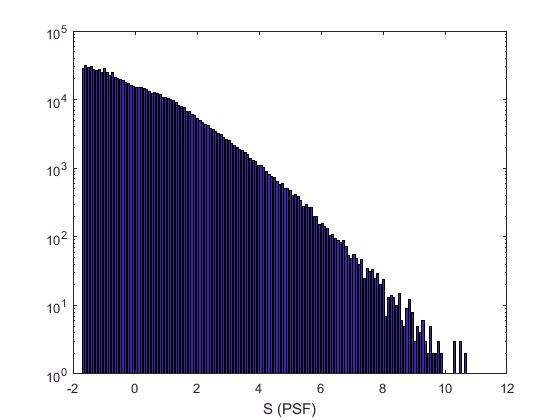

% Plot unnormalized S_PSF distribution (logarithmic Y-axis)
[counts_G,centers_G] = hist(S_PSF(:),nbins);
bar(centers,counts) 
set(gca,'YScale','log')
xlabel('S (PSF)')

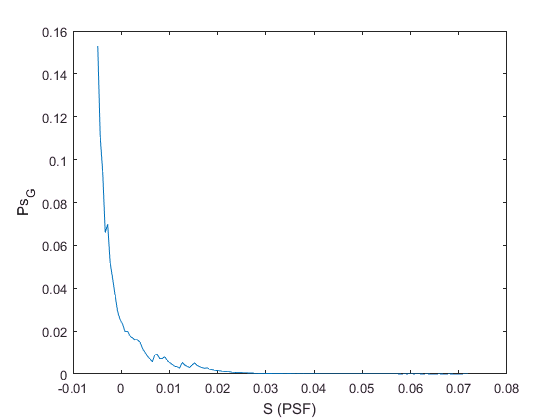

% Plot normalized Probability distribution of S_PSF (Ps_G)
Ps_G = counts_G/sum(counts_G);
plot(centers_G,Ps_G)
xlabel('S (PSF)')
ylabel('Ps_G')

The following part will be concerned with completeness calculation of the PMF method and it's comparison to the completeness of the naive method (PSF). Completeness is defined as the number of images in which the source was detected out of all images containing sources.

We consider a range of different flux values. For each flux value we generate a large number of small images containing a single source signal placed at a specific position. We filter the images with both filters (PMF and PSF) and check whether the value of the filtered image at the location of the signal is higher than the corresponding S threshold. 

% Choose the position of signal center to be added in image
Sig_pos = [round(size_TEMP_xy/2),round(size_TEMP_xy/2),round(size_TEMP_t/2)];

Flux = linspace(0.01*Fth,25,30); % Generate different flux values
Trials = 1000; % No. of trials for each flux value

Com_P = zeros(length(Flux),1); % Completeness for optimal filter (PMT)
Com_G = zeros(length(Flux),1); % Completeness for Gaussian filter (PSF)
i = 1; % Completeness index
F_c = Flux(12); % flux value for sample plots

tic
for F = Flux
    
    success_P = 0; % No. of successes for PMF method
    success_G = 0; % No. of successes for PSF method

    for N = 1:Trials
        
        % Generate random image with background subtraction
        M = makeImg(B,size_TEMP_xy,size_TEMP_t,1);
        
        % Add signal to image with a specific flux value
        M = addSignal(M,PSF,F,Sig_pos);
           
        % Filter image by 2 methods
        S_P = imfilter(M,Filter_OPT);
        S_G = imfilter(M,PSF);
        
        % Save data sample for example plots
        if (N == 1 && F == F_c)
            M_c = M;
            S_P_c = S_P;
            S_G_c = S_G;
        end
            
        
        % Check if the filtered image value at the center of the signal
        % is higher than the threshold
        Sval_P = S_P(Sig_pos(1),Sig_pos(2),Sig_pos(3));
        Sval_G = S_G(Sig_pos(1),Sig_pos(2),Sig_pos(3));
    
        if (Sval_P > Sth)
            success_P = success_P + 1;
        end
        
        if (Sval_G > Sth_G)
            success_G = success_G + 1;
        end
    end
    
    % Calculate completeness for current flux value
    Com_P(i) = success_P/Trials;
    Com_G(i) = success_G/Trials;
    i = i + 1;
end
toc

Elapsed time is 5495.046671 seconds.


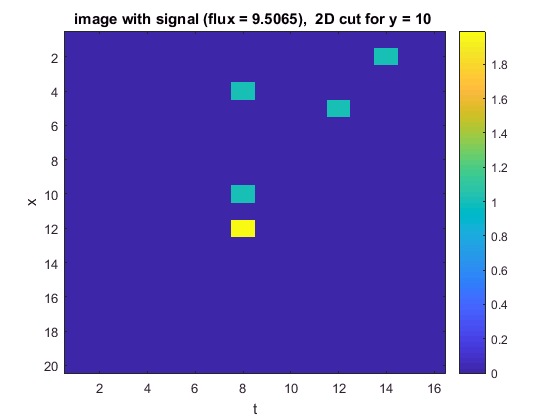

% Example 2D slice plots for a chosen data sample
plotImage(M_c,'y',Sig_pos(2),['image with signal (flux = ' num2str(F_c) '), '])

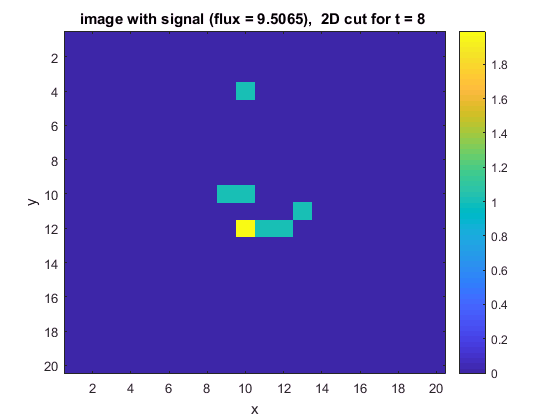


plotImage(M_c,'t',Sig_pos(3),['image with signal (flux = ' num2str(F_c) '), '])

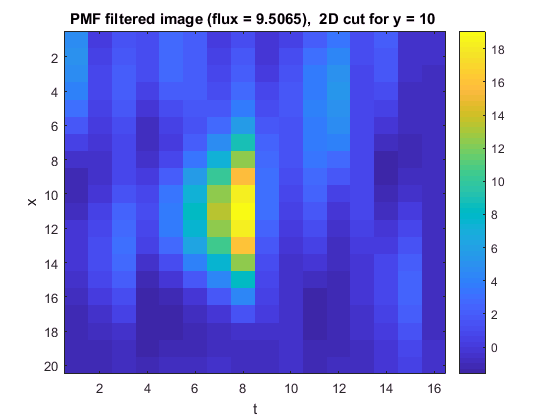

plotImage(S_P_c,'y',Sig_pos(2),['PMF filtered image (flux = ' num2str(F_c) '), '])

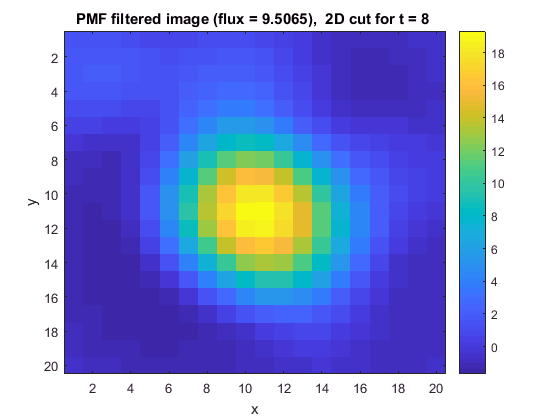

plotImage(S_P_c,'t',Sig_pos(3),['PMF filtered image (flux = ' num2str(F_c) '), '])

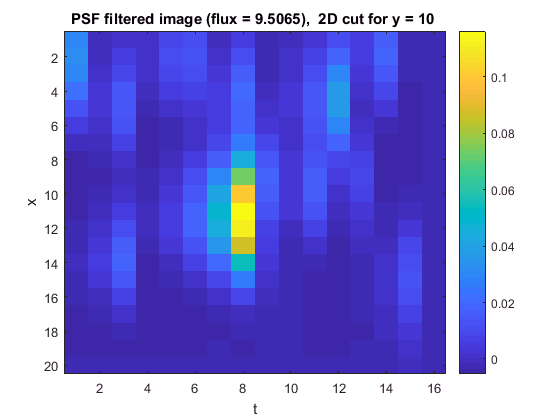

plotImage(S_G_c,'y',Sig_pos(2),['PSF filtered image (flux = ' num2str(F_c) '), '])

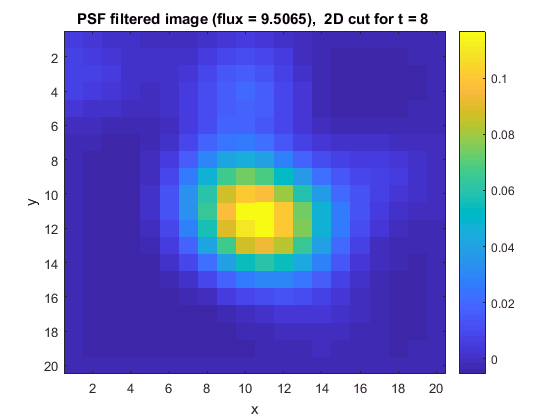

plotImage(S_G_c,'t',Sig_pos(3),['PSF filtered image (flux = ' num2str(F_c) '), '])

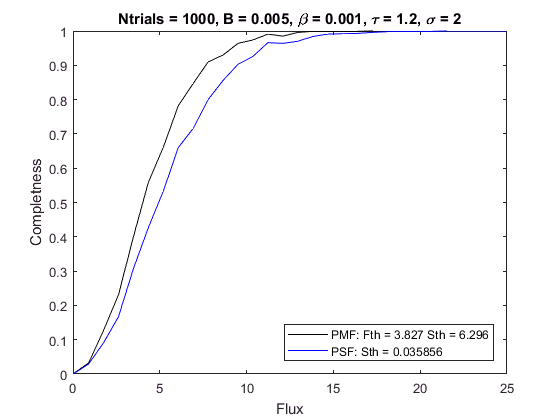

% Plot the completeness for both methods as a function of flux
plot(Flux,Com_P,'k',Flux,Com_G,'b')
legend(['PMF: Fth = ' num2str(Fth) ' Sth = ' num2str(Sth)],...
    [ 'PSF: Sth = ' num2str(Sth_G)],'Location','southeast')
title(['Ntrials = ' num2str(Trials) ', B = ' num2str(B) ...
    ', \beta = ' num2str(beta) ', \tau = ' num2str(tau) ', \sigma = ' num2str(Sigma)])
xlabel('Flux')
ylabel('Completness')